**Essentials of Ultrasound Imaging: Lecture 3**

**GUI: ABCD Matrix Calculator**

**Author: Joseph Greene**

**Reference: Chapter 3.2, Diagnostic Ultrasound Imaging: Inside Out Ed.2**

Brief Description: In this Live Editor, we will discuss how we may model electric circuits as a series of ABCD matricies. Each matrix will represent a user defined electrical element and it's frequency response. The output will be the quantity Vout/Vin and will be determined by multiplying each individual ABCD matrix together.

Inputs: Input resistor impedance, Output resistor impedance, Matrix type [Series, Shunt, Transformer, Transmission Line], 

    Transmission Line Only: Line Length (wavelengths), Transmission Line Impedance

    Transformer Only: Step-up/Step-down factor

    Else: Element type[Resistor, Capacitor, Inductor], Element impedance.

Outputs: Frequency Spectrum (Graph)

%%%%%%%%%%%%
%User Inputs
%%%%%%%%%%%%
%Input and Output Impedance
Zin = 1000; %Ohms
Zout = 1000; %Ohms

%{
    Choose Matrix Type for each matrix
    0: No Element (Short)
    1: Series
    2: Shunt
    3: Transformer
    4: Transmission Line
%}
Matrix_1 = 1;
Matrix_2 = 2;
Matrix_3 = 3;

%{
    Choose Element Type
    1: Resistor
    2: Capacitor
    3: Inductor
%}
Ele_1 = 1;
Ele_2 = 2;
Ele_3 = 3;

%Element Impedance
I_1 = 100; %ohms|nF|uH
I_2 = 200; %ohms|nF|uH
I_3 = 100; %ohms|nF|uH

%Transmission Line
lambda = 1.2; %Wavelengths
I_TL = 100; %ohms

%Transformer
n = 5;



%%%%%%%%%%%%%%%%%%%
%Generate Matricies
%%%%%%%%%%%%%%%%%%%
%Matrix 1
%First Determine Element and Impedance
syms w; %Symbol representing frequency dependance of element impedance

if Ele_1 == 1
    I_1 = I_1; %ohms

elseif Ele_1 == 2
    I_1 = -1i/(w*I_1*10^-9); %nF
    
else
    I_1 = 1i*I_1*10^-6*w; %mH
end

%Determine Matrix Type
if Matrix_1 == 0
    M_1 = [1 0;0 1];
    
elseif Matrix_1 == 1
    M_1 = [1 I_1;0 1];

elseif Matrix_1 == 2
    M_1 = [1 0;1/I_1 1];
    
elseif Matrix_1 == 3
    M_1 = [n 0; 0 1/n];
    
else
    M_1 = [cos(2*lambda/pi*w) 1j*I_TL*sin(2*lambda/pi*w); 1j*sin(2*lambda/pi*w)/I_TL cos(2*lambda/pi*w)];
end
%Check Output
M_1

M_1 =      1   100
     0     1





%Matrix 2
%First Determine Element and Impedance
if Ele_2 == 1
    I_2 = I_2; %ohms

elseif Ele_2 == 2
    I_2 = -1i/(w*I_2*10^-9); %nF
    
else
    I_2 = 1i*I_2*10^-6*w; %mH
end

%Determine Matrix Type
if Matrix_2 == 0
    M_2 = [1 0;0 1];
    
elseif Matrix_2 == 1
    M_2 = [1 I_2;0 1];

elseif Matrix_2 == 2
    M_2 = [1 0;1/I_2 1];
    
elseif Matrix_2 == 3
    M_2 = [n 0; 0 1/n];
    
else
    M_2 = [cos(2*lambda/pi*w) 1j*I_TL*sin(2*lambda/pi*w); 1j*sin(2*lambda/pi*w)/I_TL cos(2*lambda/pi*w)];
end
%Check Output
M_2

$$M\_2 = \left(\begin{array}{cc} 1 & 0\\ \frac{w\,\mathrm{i}}{5000000} & 1 \end{array}\right)$$




%Matrix 3
%First Determine Element and Impedance
if Ele_2 == 1
    I_2 = I_2; %ohms

elseif Ele_2 == 2
    I_2 = -1i/(w*I_2*10^-9); %nF
    
else
    I_2 = 1i*I_2*10^-6*w; %mH
end

%Determine Matrix Type
if Matrix_3 == 0
    M_3 = [1 0;0 1];
    
elseif Matrix_3 == 1
    M_3 = [1 I_3;0 1];

elseif Matrix_3 == 2
    M_3 = [1 0;1/I_3 1];
    
elseif Matrix_3 == 3
    M_3 = [n 0; 0 1/n];
    
else
    M_3 = [cos(2*lambda/pi*w) 1j*I_TL*sin(2*lambda/pi*w); 1j*sin(2*lambda/pi*w)/I_TL cos(2*lambda/pi*w)];
end
%Check Output
M_3

M_3 =     5.0000         0
         0    0.2000


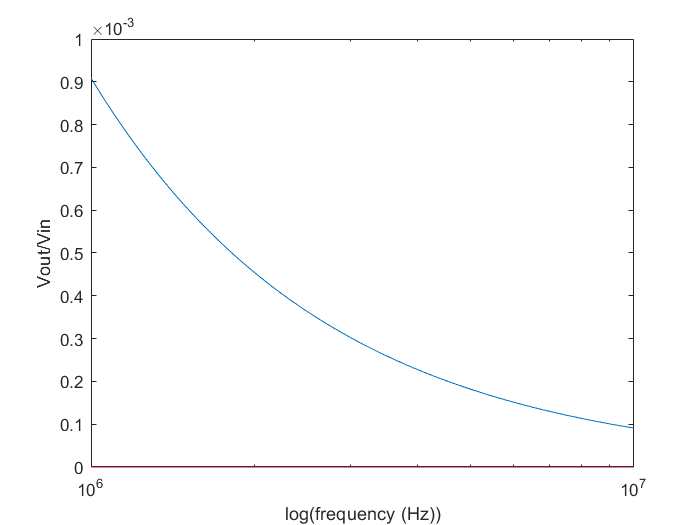



%%%%%%%%%%%%%%%
%Generate Graph
%%%%%%%%%%%%%%%
%Recall our input is a resistor in series with our defined circuit
M_in = [1 Zin;0 1]; %no dependance on w

new_w = 10.^(6:0.001:7); %Frequency Range in Hz
output = zeros(length(new_w)); %Proxy variable to save outputs

for i = 1:length(output) %Cycle through and plug in new_w(i) for w varaible
   w = new_w(i);
   mat1 = eval(subs(M_1,w));
   mat2 = eval(subs(M_2,w));
   mat3 = eval(subs(M_3,w));
   matmul = M_in*mat1*mat2*mat3;
   output(i) = (Zout)/((abs(matmul(1,1)*(Zout))+abs(matmul(1,2))));
end


semilogx(new_w,output)
ylabel('Vout/Vin')
xlabel('log(frequency (Hz))')